**2) Investigation of a Correlation between Temperature and Isotope Precipitation**

In our first attempt to investigate the relationship between temperature and isotope precipitation rate, we produced a scatterplot of local temperature as recorded in the GNIP data files against the isotope measurement. Again, we used the Valentia observatory as our first example:

% Investigating temperature dependence of isotope precipitation (scatter plot) for Valentia data

temp = sortedS.AirTemperature;

figure(4)
scatter (temp, H2, '*k')
xlabel('Temperature in °C');
ylabel('Delta D Deuterium')
axis square
box on
title ('Temperature versus Isotope Concentration for Valentia')

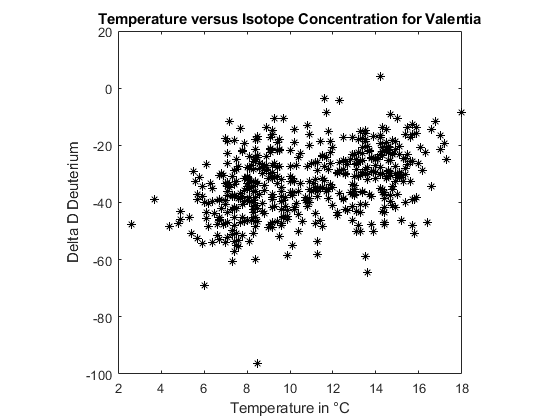

The resulting graph does not display and obvious correlation. This was to be expected, since our hypothesis is based on *average annual temperature*, not on the specific temperature at the time of precipitation. Instead of a weather dependence, it describes a correlation with the climate of a region, so in order to replicate the findings of our source paper, we need to compare geographically spread out data.

To do so, we chose six countries in different climate zones and uploaded their GNIP data into Matlab, along with climate data from the World Bank Group Climate Change Knowledge Portal ([http://sdwebx.worldbank.org/climateportal/index.cfm?page=downscaled_data_download&menu=historical](http://sdwebx.worldbank.org/climateportal/index.cfm?page=downscaled_data_download&menu=historical)):

s1 = readtable ('GeographicUK.xlsx'); % reading data from the specific Data File
s2 = readtable ('Greenland.xlsx');
s3 = readtable ('Spain.xlsx');
s4 = readtable ('Netherlands.xlsx');
s5 = readtable ('Norway.xlsx');
s6 = readtable ('Syria.xlsx');

t1 = readtable('GeographicUK_AAT.xls');
t2 = readtable('Greenland_AAT.xls');
t3 = readtable('Spain_AAT.xls');
t4 = readtable('Netherlands_AAT.xls');
t5 = readtable('Norway_AAT.xls');
t6 = readtable('Syria_AAT.xls');

We then calculated the mean and medium values of temperature and isotope precipitation for all three species. Note that while the data for deuterium and oxygen-18 is already given as delta D values, Tritium is given in TU (Tritium Units, one Tritium atom in 1018 hydrogen atoms), so we had to convert the tritium data into delta D before we display the results:

%means and medians of H2, H3, O18 and temperature for different locations
means=[mean(s1.H2,'omitnan'), mean(s1.H3,'omitnan'), mean(s1.O18,'omitnan'), mean(t1.tas,'omitnan')];
medians=[median(s1.H2,'omitnan'), median(s1.H3,'omitnan'), median(s1.O18,'omitnan'), median(t1.tas,'omitnan')];

means=[means;mean(s2.H2,'omitnan'), mean(s2.H3,'omitnan'), mean(s2.O18,'omitnan'), mean(t2.tas,'omitnan')];
medians=[medians;median(s2.H2,'omitnan'), median(s2.H3,'omitnan'), median(s2.O18,'omitnan'), median(t2.tas,'omitnan')];

means=[means;mean(s3.H2,'omitnan'), mean(s3.H3,'omitnan'), mean(s3.O18,'omitnan'), mean(t3.tas,'omitnan')];
medians=[medians;median(s3.H2,'omitnan'), median(s3.H3,'omitnan'), median(s3.O18,'omitnan'), median(t3.tas,'omitnan')];

means=[means;mean(s4.H2,'omitnan'), mean(s4.H3,'omitnan'), mean(s4.O18,'omitnan'), mean(t4.tas,'omitnan')];
medians=[medians;median(s4.H2,'omitnan'), median(s4.H3,'omitnan'), median(s4.O18,'omitnan'), median(t4.tas,'omitnan')];

means=[means;mean(s5.H2,'omitnan'), mean(s5.H3,'omitnan'), mean(s5.O18,'omitnan'), mean(t5.tas,'omitnan')];
medians=[medians;median(s5.H2,'omitnan'), median(s5.H3,'omitnan'), median(s5.O18,'omitnan'), median(t5.tas,'omitnan')];

means=[means;mean(s6.H2,'omitnan'), mean(s6.H3,'omitnan'), mean(s6.O18,'omitnan'), mean(t6.tas,'omitnan')];
medians=[medians;median(s6.H2,'omitnan'), median(s6.H3,'omitnan'), median(s6.O18,'omitnan'), median(t6.tas,'omitnan')];

According to the  reference *G. Torri, D. Ma, Z. Kuang Stable water isotopes and large-scale vertical motions in the tropics, Journal of Geophysical Research: Atmospheres Volume 122, Issue 7, pages 3703-3717, 2017 *on page 3707, the abundance of an isotope is measured with the following formula:


$$\delta D=\left(\frac{R_{\mathrm{sample}} }{R_{\mathrm{VSMOW}} }-1\right)\cdot 1000\text{ }‰$$


where:

$R_{\mathrm{sample}}$ is the ratio of the isotope to the common, stable isotope of hydrogen in the samples considered,

 $R_{\mathrm{VSMOW}}$ is the same ratio but for a reference sample with the isotopic composition of the Vienna standard mean ocean water.


$$R_{\text{VSMOW}} =1\ldotp 85\pm 0\ldotp 36\times {10}^{-11} \text{ }\mathrm{ppm}$$
 

% The H3 abundance is not given in Delta D, but in TU (Tritium atoms per 1018 Hydrogen atoms), so Delta D must be calculated:
vsmow=1.85*10^-11;   %Given in ppm 
means(:,2)=((means(:,2).*(1/1018)./vsmow)-1).*1000
medians(:,2)=((medians(:,2).*(1/1018)./vsmow)-1).*1000;

 Next we viewed our sample in form of scatterplots:

%Plot scatterplots of isotope concentration in precipitation vs temperature

scatter(means(:,4),means(:,1));     %H2 mean values
xlabel('Average Temperature in °C');
ylabel('Delta H2 (means)');
title('Climate Dependence of H2 Concentration');

scatter(medians(:,4),medians(:,1));     %H2 median values
xlabel('Average Temperature in °C');
ylabel('Delta H2 (medians)');
title('Climate Dependence of H2 Concentration');

scatter(means(:,4),means(:,2));     %H3 mean values
xlabel('Average Temperature in °C');
ylabel('Delta H3 (means)');
title('Climate Dependence of H3 Concentration');

scatter(medians(:,4),medians(:,2));     %H3 median values
xlabel('Average Temperature in °C');
ylabel('Delta H3 (medians)');
title('Climate Dependence of H3 Concentration');

scatter(means(:,4),means(:,3));     %O18 mean values
xlabel('Average Temperature in °C');
ylabel('Delta O18 (means)');
title('Climate Dependence of O18 Concentration');

scatter(medians(:,4),medians(:,3));     %O18 median values
xlabel('Average Temperature in °C');
ylabel('Delta O18 (medians)');
title('Climate Dependence of O18 Concentration');

We can see the exact dependence as described in the reference paper for deuterium and oxygen-18, but no dependence for tritium. This might be because of the high tendency of tritium samples to get contaminated, it is stated on the IAEA WISER website that the measurements for tritium often return values significantly higher than expected.

To fully validate the temperature dependence, we needed to significantly increase our sample size. For this purpose we developed a method to load whole folders of excel files into a cell array instead of uploading each table individually. The source directory has to be adjusted by each user, but this procedure enables us to sample almost the whole GNIP Database:

clear all  % Clearing workspace and figure window for this section
clf

%The following path has to be adjusted for each computer!!!!!
source_dir = 'D:/A_Karos Kram/Studium England/Year2/MAPS2001/1project/MATLAB-Isotopes-master/MATLAB-Isotopes-master/KarosContribution/';

%Load all .xls files (the climate data) into one cell array
AATdata=loadfiles(source_dir,'*.xls');

%Load all .xlsx files (the Isotope data) into one cell array
Isotopedata=loadfiles(source_dir,'*xlsx');

%Calculate the means and medians for H2, H3, O18 and Temperature across all datasets
means=zeros(size(Isotopedata,1),4); %creates arrays full of zeros of the right size
medians=zeros(size(Isotopedata,1),4);

for i= 1:length(Isotopedata)
    
   activedata=Isotopedata{i,1};                    
   tempdata=AATdata{i,1};
   
   means(i,1)=mean(activedata.H2, 'omitnan');       %Means for the isotopes
   means(i,2)=mean(activedata.H3, 'omitnan');
   means(i,3)=mean(activedata.O18, 'omitnan');
                                                
   medians(i,1)=median(activedata.H2, 'omitnan');   %Medians for the isotopes
   medians(i,2)=median(activedata.H3, 'omitnan');
   medians(i,3)=median(activedata.O18, 'omitnan');
                    
   means(i,4)=mean(tempdata.tas, 'omitnan');        %Means for temperatures
    
   medians(i,4)=median(tempdata.tas, 'omitnan');    %Medians for temperatures
   
end  

% Again, the H3 abundance is not given in Delta D, but in TU (Tritium atoms per 1018 Hydrogen atoms), so Delta D must be calculated:
vsmow=1.85*10^-11;   %Given in ppm 
means(:,2)=((means(:,2).*(1/1018)./vsmow)-1).*1000
medians(:,2)=((medians(:,2).*(1/1018)./vsmow)-1).*1000;


%Plot scatterplots of isotope concentration in precipitation vs temperature

scatter(means(:,4),means(:,1));     %H2 mean values
xlabel('Average Temperature in °C');
ylabel('Delta H2 (means)');
title('Climate Dependence of H2 Concentration');

scatter(medians(:,4),medians(:,1));     %H2 median values
xlabel('Average Temperature in °C');
ylabel('Delta H2 (medians)');
title('Climate Dependence of H2 Concentration');

scatter(means(:,4),means(:,2));     %H3 mean values
xlabel('Average Temperature in °C');
ylabel('Delta H3 (means)');
title('Climate Dependence of H3 Concentration');

scatter(medians(:,4),medians(:,2));     %H3 median values
xlabel('Average Temperature in °C');
ylabel('Delta H3 (medians)');
title('Climate Dependence of H3 Concentration');

scatter(means(:,4),means(:,3));     %O18 mean values
xlabel('Average Temperature in °C');
ylabel('Delta O18 (means)');
title('Climate Dependence of O18 Concentration');

scatter(medians(:,4),medians(:,3));     %O18 median values
xlabel('Average Temperature in °C');
ylabel('Delta O18 (medians)');
title('Climate Dependence of O18 Concentration');

The relationship only holds for average temperatures up to 15°C, so all datasets from countries with a higher annual temperature have to be sorted out:

%First, collect all mean and median values for temperatures below 15°C only
m=1;
n=1;
for k=1:length(means)
    if means(k,4)<=15
        behavedmeans(m,:)=means(k,:);        %Means that theoretically follow the relationship
        m=m+1;
    end
    if medians(k,4)<=15
        behavedmedians(n,:)=medians(k,:);    %Medians that theoretically follow the relationship
        n=n+1;
    end
end

%Plot these relevant regions
scatter(behavedmeans(:,4),behavedmeans(:,1));
xlabel('Average Temperature in °C');
ylabel('Delta H2 (means)');
title('Approximately Linear Region for Climate Dependence of H2');

scatter(behavedmedians(:,4),behavedmedians(:,1));
xlabel('Average Temperature in °C');
ylabel('Delta H2 (medians)');
title('Approximately Linear Region for Climate Dependence of H2');

scatter(behavedmeans(:,4),behavedmeans(:,3));
xlabel('Average Temperature in °C');
ylabel('Delta O18 (means)');
title('Approximately Linear Region for Climate Dependence of O18');

scatter(behavedmedians(:,4),behavedmedians(:,3));
xlabel('Average Temperature in °C');
ylabel('Delta H3 (medians)');
title('Approximately Linear Region for Climate Dependence of O18');

Next we want to find out whether means or medians provide the better linear regression and which Isotope most closely  abides a linear relationship. We use a function which inputs minimum two arrays of equal size and calculates a line of best fit for the first array against all the others in turn.

H2Fit=fitfunction(behavedmeans(:,4),behavedmeans(:,1),behavedmedians(:,1))
O18Fit=fitfunction(behavedmeans(:,4),behavedmeans(:,3),behavedmedians(:,3))
BestFit=fitfunction(behavedmeans(:,4),behavedmeans(:,1),behavedmedians(:,1),behavedmeans(:,3),behavedmedians(:,3))

figure(2)
plot(BestFit{1},behavedmeans(:,4), behavedmeans(:,3));
xlabel('Average Annual Temperature in °C');
ylabel('Delta D O18 (means)');
title('Best Fitting Linear Regression Line: O18 (means)');

Coefficients=BestFit{1}

The following computation is incomplete, it represents first efforts towards refining the above process and incorporating the mapping toolbox to represent data on different projections of the earth.

n=1;                %Presetting variables to count iterations
m=1;
plotme=[];

for i=1:length(Isotopedata)     %This loop iterates over every loaded excel file, ergo every country
    
    activedata=Isotopedata{i};  
    latitudes=activedata.Latitude;
    longitudes=activedata.Longitude;
    H2=activedata.H2;           %For every excel table, latidudes, longitudes and the deuterium data is separated
    
    for j=1:(height(activedata))        %In this loop all isotope values are saved in one array as long as the geographical coordinates remain unchanged --> the data is separated by station
        holdisotopes(m)=H2(j);
        m=m+1;
        
        if j~=height(activedata)
            if (latitudes(j)~=latitudes(j+1))||(longitudes(j)~=longitudes(j+1))         % As soon as a new location provides data in the next row, all previously held data is saved and averaged if necessary
                plotme(n,:)=[latitudes(j), longitudes(j), mean(holdisotopes, 'omitnan')];
                holdisotopes=[];                            %This resets all hold variables
                m=1;
                n=n+1;
            end
        else
            plotme(n,:)=[latitudes(j), longitudes(j), mean(holdisotopes, 'omitnan')]; %When the table ends the same process as when the station changes is initiated
            holdisotopes=[];                        %Also resetting container variables
            m=1;
            n=n+1;
        end
    end
end

plotme=rmmissing(plotme);           %Plotme is a N-by-3 array connecting geographical coordinates to the monthly average deuterium precipitation

This code can be used to refine the temperature dependence analysis, it allows handling each station individually instead by country. Furthermore, the geolocated isotope values can be projected onto the earth with the mapping toolbox. First familiarisations with the toolbox can be seen below:

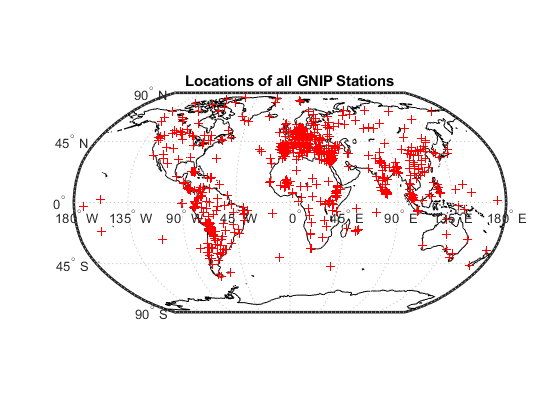

worldmap('World');
load coastlines;
plotm(coastlat,coastlon,'k');

geoshow(plotme(:,1),plotme(:,2),'DisplayType','point');
title('Locations of all GNIP Stations')

Functions used in this script. They could be moved to an external file.

function bestfit=fitfunction(X,varargin)    %fitfunction accepts a variable number of input arguments
    
    gof=zeros(length(varargin),1);          %Create an empty array to hold the coefficients of determination for later comparison
    
    for i=1:length(varargin)                %For every given possible y-value dataset...
        [~, gofi]=fit(X,varargin{i},'poly1');   %...a 1st degree polynomial is fitted...
        gof(i)=gofi.rsquare;                %... and the coeffitient of determination is retained
    end
    
    [bestgof, gofnb]=max(gof);              %The y-value dataset which provides the highest R² (--> the best fit) is determined
    coefficients=fit(X,varargin{gofnb},'poly1'); %Calculate the coefficients for the linear equation describing the best fit
    
    bestfit={coefficients,bestgof,gofnb+1};   %The function outputs the best fit coefficients, the corresponding R² and the number of the input variable that provides the best fit
end

function loadedfiles=loadfiles(filepath, filextension)  %The complete file path and file extension are needed
    
source_files = dir(fullfile(filepath, filextension));   %The fullfile function merges file name fragments and the dir function lists all files the thereby specified folder which have the given extension
loadedfiles=cell(size(source_files));                   %Precreate an empty cell array for all files to be loaded
      
    for i = 1:length(source_files)
      loadedfiles{i} = readtable(fullfile(filepath, source_files(i).name));  %One by one, every excel file identified above is loaded into Matlab using the readtable function
    end
end





